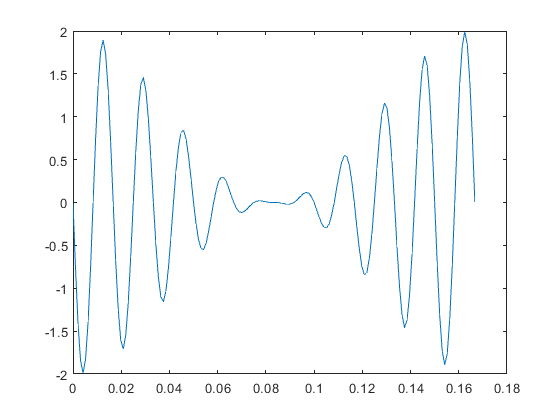

Fs = 960;
%{
Type = 'Phase Modulation';
Freq = [4 6 8 10 12 14 16];
Index = [1 1 1 1 1 1 1];
Phase = [0 0 0 0 0 0 0];
Damping = [0 0 0 0 0 0 0];
%}
Type = 'Amplitude Modulation';
Freq = [54 60 66];
Index = [1 1 1];
Phase = [0 0; 90 0; 0 0];
Damping = [0 0 0];
Handle = 'foo';

%Type = 'Amplitude Modulation';
%Freq = [59 60 61];
%Index = [.1 1 .1];
%Phase = [45 90 45];

[A,C,X] = CalcStateMatrix(Fs,Type,Freq,Index,Phase,Damping,Handle);

duration = 1/6;
T = 1/Fs;
k = (0:1:duration*Fs);
X = zeros(length(k),length(Freq)*2);
for n = 1:length(Freq)
    X(1,(2*(n-1))+1)=1;
end

C(2,1:2)=C(1,1:2);
C(3,5:6)= C(1,5:6);
%C(1,1:2)= [0 0];
%C(1,5:6)=[0 0];

Y = zeros(length(k),length(Freq)*2);
n = 2;
for n = k+2
    Y(n-1,:) = C*X(n-1,:)';
    X(n,:)=A*X(n-1,:)';   
end

%plot(k*T,Y(:,1:3))
plot (k*T,Y(:,1))